#### Escuela Superior de Ingeniería y Tecnología (UNIR)

## Máster Universitario en Ingeniería Matemática y Computación

### - OPTIMIZACIÓN -

# Actividad 1: Optimización de funciones

**Alumno:** Pablo Ruiz Molina

## 1. Selección de intervalo de longitud 1 de las funciones test

En el primer apartado de esta actividad se busca seleccionar un intervalo de longitud 1, en el cual la función sea unimodal y contenga el mínimo localizado en el valor positivo más pequeño. Para entender qué tipo de funciones hay que enfrentar, se ha optado en primer lugar por visualizarlas. Se han escogido rangos ciertamente amplios para entender las funciones de manera general. El código usado para ello es el siguiente:

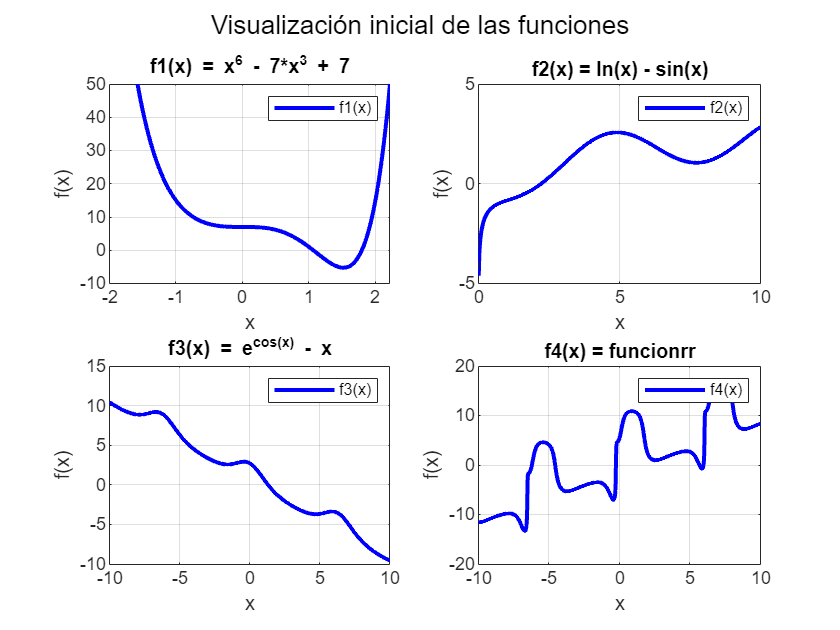

% Visualización inicial de las funciones 
clc; clear; close all;

% Definición de las funciones objetivo
f1 = @(x) (x.^6) - 7*(x.^3) + 7;
f2 = @(x) log(x) - sin(x);
f3 = @(x) exp(1).^cos(x) - x;
f4 = @(x) funcionrr(x);
%f4 = @(x) (x-2).^2;

funciones_id = {'f1(x)'; 'f2(x)'; 'f3(x)'; 'f4(x)'};
f = {f1; f2; f3; f4};

%% Visualización inicial
x1_values = linspace(-10, 10, 1000); y1_values = f1(x1_values);
x2_values = linspace(  0, 10, 1000); y2_values = f2(x2_values);
x3_values = linspace(-10, 10, 1000); y3_values = f3(x3_values);
x4_values = linspace(-10, 10, 1000); y4_values = f4(x4_values);

x_values = [x1_values; x2_values; x3_values; x4_values];
y_values = [y1_values; y2_values; y3_values; y4_values];

figure (1)
subtitles = {'f1(x) = x^6 - 7*x^3 + 7';
             'f2(x) = ln(x) - sin(x)';
             'f3(x) = e^{cos(x)} - x';
             'f4(x) = funcionrr'};
ylims = [[-10, 50]; [-5, 5]; [-10, 15]; [-20, 20]];
legends = {'f1(x)'; 'f2(x)'; 'f3(x)'; 'f4(x)'};

for i = 1:4
    subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
    title(subtitles{i},'Interpreter', 'tex');
    ylim(ylims(i,:));
    xlabel('x');
    ylabel('f(x)');
    legend(legends{i});
    hold on;
    grid on;
end

sgtitle('Visualización inicial de las funciones');

A destacar cómo la segunda función $\left(f_2 \left(x\right)\right)$  cuenta con un límite de $-\infty$ en $x\ =\ 0$. Es de hecho esperable según el rango donde se define la función en el enunciado: $\left(0,\ \infty \right)$. 

Es fácil seleccionar para cada función un intervalo unidad en el que la función sea unimodal, con un mínimo, y que a su vez sea el más cercano a 0 por la parte positiva.

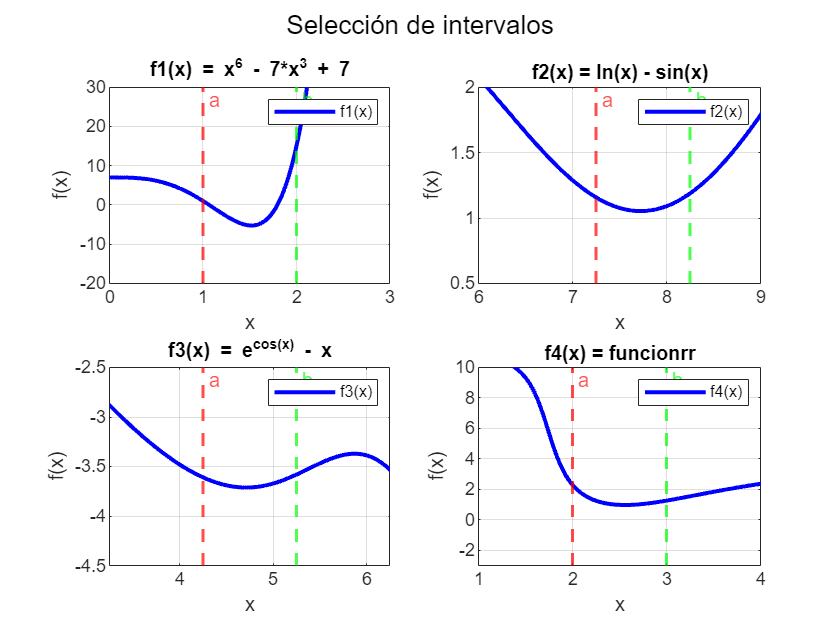

%% Selección del intervalo de búsqueda de cada función
intervalo_f = [[1, 2]; [7.25, 8.25]; [4.25, 5.25]; [2, 3]];

xlims = [[0, 3]; [6, 9]; [3.25, 6.25]; [1, 4]];
ylims = [[-20, 30]; [0.5, 2]; [-4.5, -2.5]; [-3, 10]];

% Visualización de los intervalos
figure (2);
for i = 1:4
    subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
    subplot(2, 2, i), xline(intervalo_f(i, 1), '--r', 'a', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
    subplot(2, 2, i), xline(intervalo_f(i, 2), '--g', 'b', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
    title(subtitles{i},'Interpreter', 'tex');
    xlim(xlims(i,:));
    ylim(ylims(i,:));
    xlabel('x');
    ylabel('f(x)');
    legend(legends{i});
    hold on;
    grid on;
end

sgtitle('Selección de intervalos');

## 2. Métodos de búsqueda

Una vez los intervalos de búsqueda están seleccionados, se van a desarrollar y probar los diferentes métodos de búsqueda objetivo de la actividad.

### 2.1 Método de búsqueda dicotómica

La búsqueda dicotómica es un método simple y eficiente diseñado para encontrar el mínimo de una función unimodal dentro de un intervalo dado. Este tipo de función tiene una sola tendencia descendente seguida de una ascendente (o viceversa), garantizando que exista un único mínimo local dentro del intervalo considerado. El algoritmo es iterativo y trabaja reduciendo progresivamente el tamaño del intervalo donde se encuentra el mínimo, basándose en evaluaciones estratégicas de la función en puntos seleccionados dentro del intervalo. El código implementado ha sido el siguiente:

function [x_min, iter] = budi(f, a, b, delta)
    % Método de búsqueda dicotómica
    % Entradas:
    %   f: función objetivo
    %   a, b: extremos iniciales del intervalo unimodal
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método

    % Valores iniciales
    eps = delta/10; % Siempre más pequeño que la tolerancia.

    % Inicialización de las variables
    iter = 0;  % Contador de iteraciones
    max_iter = 100;  % Número máximo de iteraciones
    
    while (b - a) > delta && iter < max_iter
        iter = iter + 1;

        % Calcular xa y xb
        x = (a + b)/2; 
        xa = x - eps/2;
        xb = x + eps/2;

        % Evaluar la función en los extremos del nuevo intervalo
        if f(xa) < f(xb)
            b = xb;
        else
            a = xa;
        end
    end
    % Cálculo del mínimo
    x_min = (a + b) / 2;
end

En este algoritmo de búsqueda se puede destacar cómo hay que evaluar la función en cada extremo del intervalo (2 veces por iteración). También se puede destacar la clave del algoritmo, que es la comprobación de las propias evaluaciones, con la cual se cierra el intervalo por el lado de la función que quedé más positivo. Los resultados obtenidos una vez se pasa el algoritmo a todas las funciones son los siguientes:

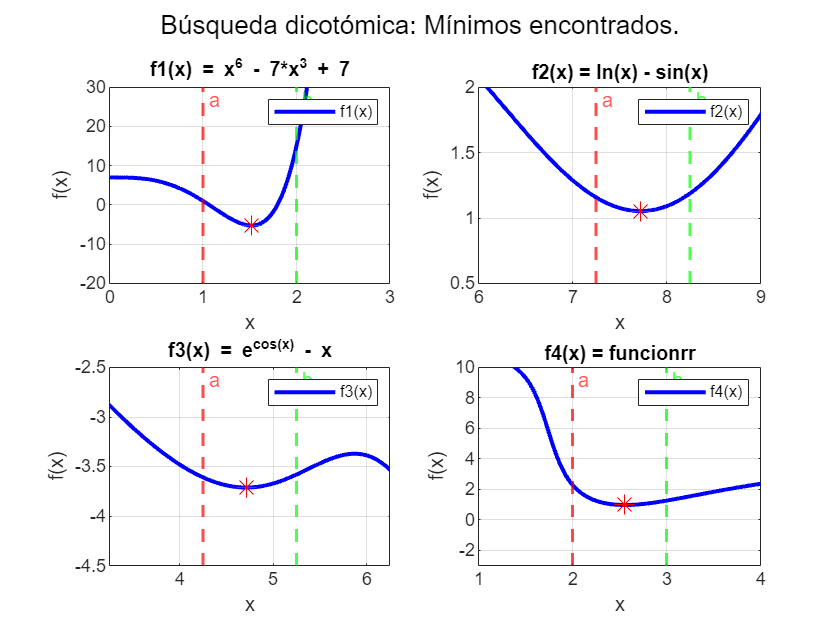

% Parámetros de la interpolación cuadrática
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_budi = zeros(1, 4); 
iter_budi = zeros(1, 4);
tiempos_budi = zeros(1, 4);
f_min_budi = zeros(1, 4);
for i = 1:4
    tic;
    [x_min_budi(i), iter_budi(i)] = budi(f{i}, intervalo_f(i, 1), intervalo_f(i, 2), delta);
    tiempos_budi(i) = toc * 1000;
    f_min_budi(i) = f{i}(x_min_budi(i));
end

% Representación de los resultados para cada función
figure (4)
titulo_budi = 'Búsqueda dicotómica: Mínimos encontrados.';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_budi, f_min_budi, subtitles, legends, titulo_budi)

Se aprecia a simple vista cómo se encuentra el punto mínimo en cada una de las funciones de manera precisa. En la siguiente tabla se detallan los valores obtenidos para el valor $x_{\min }$, para el valor que cobra la función $f\left(x_{\min } \right)$, para las iteraciones necesarias, así como para el tiempo de ejecución:

% Tabla comparativa
T_budi = table(funciones_id, x_min_budi', f_min_budi', iter_budi', tiempos_budi', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_budi);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25         21             0.6897    
    {'f2(x)'}    7.7242     1.0528         21             0.5869    
    {'f3(x)'}    4.7124    -3.7124         21             0.3208    
    {'f4(x)'}    2.5574    0.97258         21             198.91    



Será interesante comparar con los siguientes métodos los resultados de los valores $x_{\min }$ y $f\left(x_{\min } \right)$, aunque a priori, visualmente, parecen muy correctos. 

En relación con las iteraciones, es interesante notar cómo para todas las funciones se consume el mismo número de ellas, 21 en este caso. Se puede calcular las iteraciones mínimas necesarias por este algoritmo, en base a la tolerancia escogida:

% Cálculo de las iteraciones mínimas de Budi
iter_min_budi = log(delta)/log(.5);
disp(['Número de iteraciones mínimas para búsqueda dicotómica: iter_min <= ', num2str(ceil(iter_min_budi))])

Número de iteraciones mínimas para búsqueda dicotómica: iter_min <= 20


Se aprecia cómo de acuerdo al parámetro delta escogido, son 20 iteraciones como mínimo. Como se comentaba, en los 4 casos se han consumido 21 iteraciones, lo cuál, como mínimo, entra dentro de lo esperado. 

En cuanto al tiempo de ejecución, se observa cómo para $f_1 \left(x\right),\;f_2 \left(x\right)\;y\;f_3 \left(x\right)$ el valor ronda entre 0.5-1.5 milisegundos, mientras que para $f_4 \left(x\right)$ el tiempo se dispara hasta casi los 200 milisegundos. Esto se debe a que las evaluciones que necesita hacer la función son en esta última función mucho más costosas por ser una función numérica un tanto compleja.

### 2.2 Método de interpolación cuadrática (*incu.m*)

La interpolación cuadrática es un método iterativo y eficiente para encontrar el mínimo de una función dentro de un intervalo dado. Este método asume que la función puede ser aproximada localmente por una parábola y utiliza tres puntos del intervalo para construir esta aproximación cuadrática. A partir de esta parábola se estima el punto donde ocurre el mínimo, lo que permite ajustar el intervalo para acercarse progresivamente al mínimo real. El proceso se repite iterativamente hasta alcanzar una precisión deseada, refinando el intervalo en cada paso y mejorando la aproximación del mínimo. El código implementado ha sido el siguiente:

function [x_min, iter] = incu(f, x1, x2, x3, delta)
    % Método de interpolación cuadrática
    % Entradas:
    %   f: función objetivo
    %   x1, x2, x3: puntos iniciales en los que x2<x1 y x2<3
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método
    % Inicialización de las variables
    iter = 0;  % Contador de iteraciones
    max_iter = 100;  % Número máximo de iteraciones
    
    while iter < max_iter 
        iter = iter + 1;

        % Calcular el valor mínimo del polinomio interpolador
        f1 = f(x1); f2 = f(x2); f3 = f(x3);
        num = ((x2^2-x3^2)*f1 + (x3^2-x1^2)*f2 + (x1^2-x2^2)*f3);
        den = 2*((x3-x2)*f1 + (x1-x3)*f2 + (x2-x1)*f3);
        x = -num/den;
        
        % Se cumple el criterio de parada?
        if abs(x2 - x) < delta
            x_min = x;
            return
        else
            % Se reduce el intervalo
            if x2 <= x
                x1 = x2; x2 = x; 
            else
                x3 = x2; x2 = x;
            end
        end
    end
    x_min = 0;

end

En este caso, lo más destacable es el cálculo del mínimo del polinomio interpolador, realizado de acuerdo a las conclusiones del desarrollo teórico del método. También es interesante notar cómo en cada iteración se necesita evaluar la función 3 veces. Esto es una vez más que en el método de la búsqueda dicotómica, lo que a priori lo pondría en desventaja. Como se verá a continuación, la parte positiva es que requiere menos iteraciones para obtener el mínimo. Los resultados obtenidos una vez se pasa el algoritmo a todas las funciones son los siguientes:

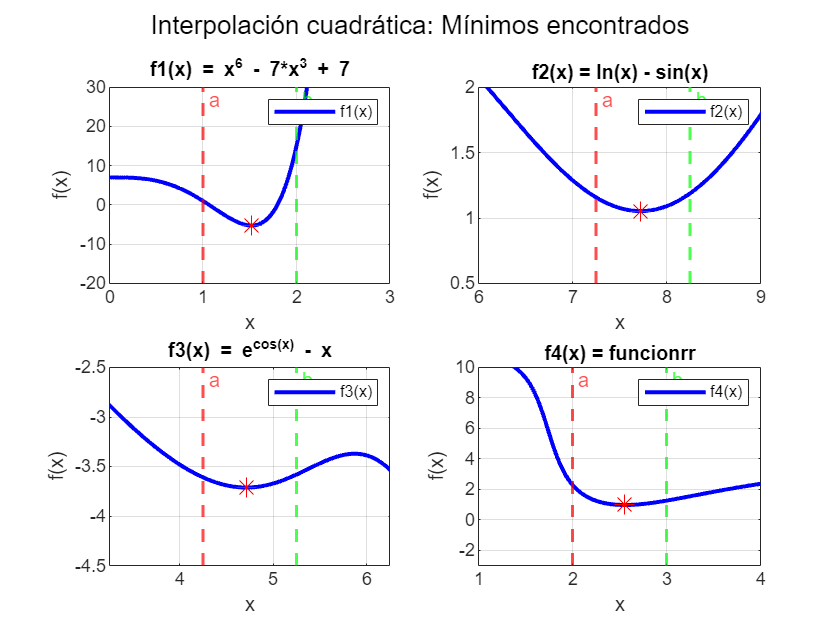

% Parámetros de la interpolación cuadrática
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_incu = zeros(1, 4); 
iter_incu = zeros(1, 4);
tiempos_incu = zeros(1, 4);
f_min_incu = zeros(1, 4);
for i = 1:4
    tic;
    [x_min_incu(i), iter_incu(i)] = incu(f{i}, intervalo_f(i, 1), (intervalo_f(i, 1) + intervalo_f(i, 2))/2, intervalo_f(i, 2), delta);
    tiempos_incu(i) = toc * 1000;
    f_min_incu(i) = f{i}(x_min_incu(i));
end

% Representación de los resultados para cada función
figure (5)
titulo_incu = 'Interpolación cuadrática: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_incu, f_min_incu, subtitles, legends, titulo_incu)

Se aprecia a simple vista cómo se encuentra el punto mínimo en cada una de las funciones de manera precisa. En la siguiente tabla se detallan los valores obtenidos para $x_{\min }$, $f\left(x_{\min } \right)$, para las iteraciones necesarias, así como para el tiempo de ejecución:

% Tabla comparativa
T_incu = table(funciones_id, x_min_incu', f_min_incu', iter_incu', tiempos_incu', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_incu);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25          9             0.5296    
    {'f2(x)'}    7.7242     1.0528          5             0.4061    
    {'f3(x)'}    4.7124    -3.7124          5             0.0883    
    {'f4(x)'}    2.5574    0.97258          7             96.048    



Se puede comprobar cómo los valores mínimos obtenidos coinciden con el método de búsqueda dicotómica. 

En relación con las iteraciones, es interesante notar como ahora hay dos funciones que ocupan 5 iteraciones ($f_2 \left(x\right)$ y $f_3 \left(x\right)$) mientras que $f_4 \left(x\right)$ ocupa 7 y $f_1 \left(x\right)$ ocupa 9. De manera intuitiva se puede identificar que en aquellas funciones donde el mínimo tiene menos pendiente, se hace más complicado para el método cerrar el intervalo y por tanto tarda más iteraciones.

En cuanto al tiempo de ejecución, se observa cómo para las tres primeras funciones el valor ronda entre 0.5-1 milisegundos, mientras que para $f_4 \left(x\right)$ el tiempo se dispara hasta casi los 100 milisegundos. Esto se debe de nuevo a que las evaluciones que necesita hacer la función son en esta última función mucho más costosas por ser una función numérica un tanto compleja.

### 2.3 Método de Newton (new*.m*)

El método de Newton es un método iterativo y eficiente para encontrar el mínimo de una función utilizando información de su derivada y derivada segunda. Este método asume que la función puede aproximarse localmente mediante una parábola utilizando una expansión en serie de Taylor de segundo orden. En cada iteración, calcula el punto donde la derivada de la parábola se anula, estimando así el próximo valor del mínimo. Este nuevo punto se convierte en la base para la siguiente iteración, refinando progresivamente la aproximación al mínimo real. A continuación se adjunta el código empleado:

function [x_min, iter] = new(f, intervalo, delta)
    % Método de Newton
    % Entradas:
    %   f: función objetivo
    %   intervalo: intervalo objetivo
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método
    % Valores iniciales
    iter = 0;
    max_iter = 100;  % Número máximo de iteraciones
    error1 = delta + 1;
    error2 = delta + 1;
    h = 1/1000; % Cada función está muestreada con 1000 muestras.
    x_n = intervalo(1) + (intervalo(2) - intervalo(1))/2; % x inicial = Punto medio del intervalo

    while (error1 > delta || error2 > delta) && iter < max_iter
        iter = iter + 1;

        % Se evaluan las derivadas usando aproximación de diferencias
        % finitas centrales
        fx_2h = f(x_n + 2*h); fx_h = f(x_n + h); fx_nh = f(x_n - h); fx_2nh = f(x_n - 2*h);
        f_p = (-fx_2h + 8*fx_h - 8*fx_nh + fx_2nh)/(12*h);
        f_pp = (-fx_2h + 16*fx_h - 30*f(x_n) + 16*fx_nh - fx_2nh)/(12*(h^2));

        % Se actualiza el valor de x_n + 1
        x_n_1 = x_n - f_p/f_pp;

        % Se evaluan los errores
        error1 = abs(x_n_1 - x_n);
        f_p = (-f(x_n_1 + 2*h) + 8*f(x_n_1 + h) - 8*f(x_n_1 - h) + f(x_n_1 - 2*h))/(12*h);
        error2 = abs(f_p);
        
        % Se actualiza x_n, que será el mínimo si no hay más iteraciones
        x_n = x_n_1;
        x_min = x_n;
    end
end

De este código hay que comentar que se ha usado la aproximación en diferencias finitas centrales para calcular tanto la primera derivada como la segunda. Esto es así dado que $f_4 \left(x\right)$ no permitía calcular las derivadas mediante expresiones simbólicas. Por otro lado, cabe comentar que en cada iteración hay que hacer al menos 8 evaluaciones de la función, 4 sobre el valor $x_n$ para las aproximaciones de $f^{\prime } \left(x_n \right)$ y$f^{\prime \prime } \left(x_n \right)$, y otras 4 para aproximar $f^{\prime } \left(x_{n+1} \right)$. Esto puede compensar, no obstante, al hecho de que converga más rápido que los dos métodos anteriores. A continación se muestran los resultados:

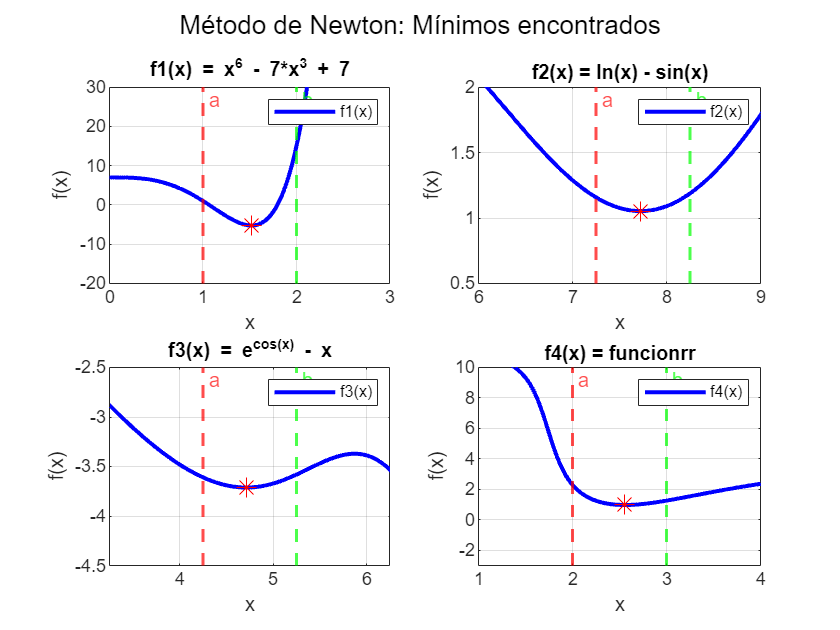

% Parámetros del método de Newton
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_new = zeros(1, 4); 
iter_new = zeros(1, 4);
tiempos_new = zeros(1, 4);
f_min_new = zeros(1, 4);

for i = 1:4
    tic;
    [x_min_new(i), iter_new(i)] = new(f{i}, intervalo_f(i,:), delta); 
    tiempos_new(i) = toc * 1000;
    f_min_new(i) = f{i}(x_min_new(i));
end

% Representación de los resultados para cada función
figure(6)
titulo_new = 'Método de Newton: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_new, f_min_new, subtitles, legends, titulo_new)

Los mínimos son correctos a simple vista. En la siguiente tabla se detallan los valores obtenidos para el valor $x_{\min }$, para $f\left(x_{\min } \right)$, para las iteraciones necesarias, así como para el tiempo de ejecución:

% Tabla comparativa
T_new = table(funciones_id, x_min_new', f_min_new', iter_new', tiempos_new', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_new);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25          3              0.771    
    {'f2(x)'}    7.7242     1.0528          3             0.5924    
    {'f3(x)'}    4.7124    -3.7124          3             0.0462    
    {'f4(x)'}    2.5574    0.97258          4             166.95    



Se aprecia como los mínimos vuelven a ser correctos. En cuanto a las iteraciones, en este caso, el método se toma menos que los dos anteriores, por lo que se considera más eficiente. Los  tiempos sin embargo no son excelentes, debido en gran parte a la gran cantidad de evaluaciones que requiere hacer sobre la función para aproximar la derivada. No obstante, este tiempo se podría reducir si se usara un orden menor para dicha aproximación.

### 2.4 Método de las rectas inexactas (rein*.m*)

El método de las rectas inexactas trata de un procedimiento iterativo utilizado para encontrar el mínimo de una función a lo largo de una dirección determinada basada en el gradiente. Este método se basa en primer lugar en ajustar el intervalo de búsqueda en cada iteración, basándose en condiciones específicas (Armijo y Wolfe) que aseguran un descenso suficiente y una convergencia estable; para posteriormente actualizar el valor mínimo usando la dirección y el intervalo de búsqueda. El proceso se repite iterativamente, refinando la estimación del mínimo hasta alcanzar un nivel de precisión deseado. A continuación se adjunta el código empleado:

function [x_min, iter] = rein(f, intervalo, alpha, beta, delta)
    % Método de las rectas inexactas con las condiciones de Armijo y Goldstein.
    %
    % Entradas:
    %   f        - Función objetivo (handle)
    %   intervalo- Intervalo donde seleccionar el punto inicial
    %   alpha    - Parámetro para las condiciones (0 < alpha < 0.5)
    %   beta     - Factor de reducción del paso (0 < beta < 1)
    %   eps      - Tolerancia para la convergencia
    %
    % Salidas:
    %   x_min    - Punto aproximado donde se alcanza el mínimo
    %   iter     - Número de iteraciones realizadas

    % Inicialización
    iter = 0;
    % x inicial = Punto medio del intervalo
    xk = intervalo(1) + (intervalo(2) - intervalo(1))/2; 
    max_iter = 100;
    
    grad_lambda_d = 1; % Para no cumplir el criterio de parada al inicio

    % Paso de la señal. -> Aproximar gradiente
    h = 1/1000; % Tamaño de paso 
    
    while abs(grad_lambda_d) > delta && iter < max_iter
     
        if (iter == 0)
            % En iter 0, hay que calcular el gradiente de f(xk) por primera vez.
            fx_2h = f(xk + 2*h); fx_h = f(xk + h); fx_nh = f(xk - h); fx_2nh = f(xk - 2*h);
            grad = (-fx_2h + 8*fx_h - 8*fx_nh + fx_2nh)/(12*h);
        else
            % El gradiente de f(xk) será el mismo que el gradiente de f(xk-1 +
            % lambda_d) calculado en la iteración anterior.
            grad = grad_lambda_d;
        end
        
        % Cálculo de la dirección
        d = -grad;

        % Para cada salto, se empieza considerando lambda = 1
        lambda = 1;

        % Evaluación de la función en xk y xk + lambda_d
        fxk = f(xk);
        fxk_lambda_d = f(xk + lambda*d);
        
        % Cálculo de grad(f(xk + lambda*d)) mediante aproximación de diferencias
        % finitas 
        fx_2h_lambda_d = f(xk + lambda*d + 2*h); fx_h_lambda_d = f(xk + lambda*d + h); fx_nh_lambda_d = f(xk + lambda*d - h); fx_2nh_lambda_d = f(xk + lambda*d - 2*h);
        grad_lambda_d = (-fx_2h_lambda_d + 8*fx_h_lambda_d - 8*fx_nh_lambda_d + fx_2nh_lambda_d)/(12*h);

        % Revisión de las condiciones de Armijo y Goldstein
        while ((fxk_lambda_d > fxk + alpha*lambda*grad*d) || (beta*grad*d > grad_lambda_d*d))
            % Actualizo lambda
            lambda = 0.5*lambda;
            
            % Actualizo grad(f(xk + lambda*d))
            fx_2h_lambda_d = f(xk + lambda*d + 2*h); fx_h_lambda_d = f(xk + lambda*d + h); fx_nh_lambda_d = f(xk + lambda*d - h); fx_2nh_lambda_d = f(xk + lambda*d - 2*h);
            grad_lambda_d = (-fx_2h_lambda_d + 8*fx_h_lambda_d - 8*fx_nh_lambda_d + fx_2nh_lambda_d)/(12*h);
            
            % Actualización de la evaluación de la función en lambda
            fxk_lambda_d = f(xk + lambda*d);

            % Prevenir bucles infinitos.
            if lambda < 0.00001
                break;
            end
        end 
        
        % Actualización de xk con el lambda obtenido
        xk = xk + lambda*d;
        iter = iter + 1;

    end
    % Mínimo
    x_min = xk;
end

De este código se pueden destacar varias cosas. En primer lugar, comentar que para calcular los gradientes necesarios se ha vuelto a usar la aproximación de las diferencias finitas para evitar problemas con funciones definidas numéricamente. En segundo lugar, las condiciones de Armijo y Goldstein han sido revisadas consecuentemente, y cuando una de estas dos no se cumple, se actualiza el valor de lambda haciéndolo más pequeño, pero a la misma vez maximizando su valor. Por último, comentar como, para hacer el algoritmo más eficiente, una vez se pasa la iteración 0, no se vuelve a calcular el gradiente de$f\left(x_k \right)$ dado que sería el mismo que el calculado anteriormente: $f\left(x_{k-1} +\lambda \mathit{\mathbf{d}}\right)$. A continuación se representan los resultados obtenidos para las 4 funciones:

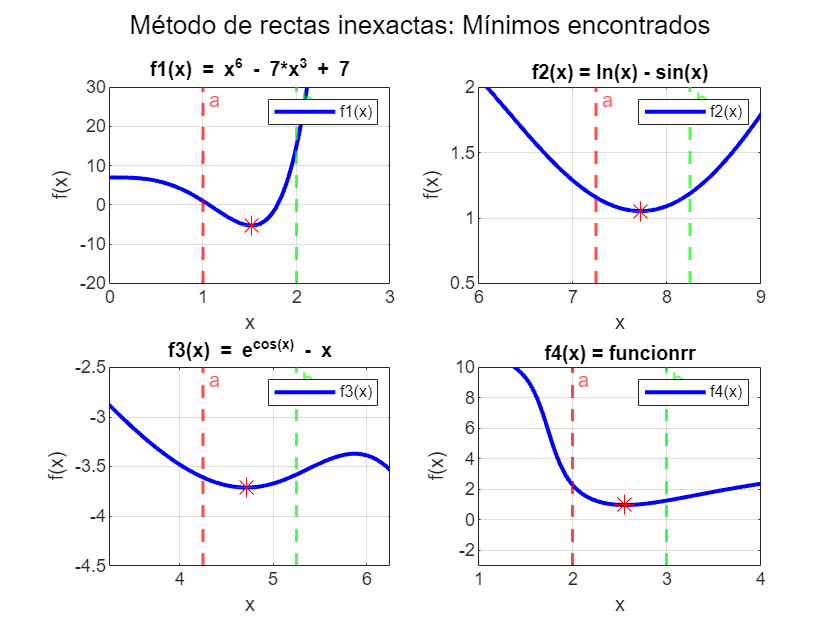

% Parámetros del método de rectas inexactas
eps = 1e-6;  % Tolerancia (epsilon)
alpha = 10^-4; beta = 10^-1; % Consideracioens inciales

% Ejecución del método para cada función
x_min_rein = zeros(1, 4); 
iter_rein = zeros(1, 4);
tiempos_rein = zeros(1, 4);
f_min_rein = zeros(1, 4);

for i = 1:4
    tic;
    [x_min_rein(i), iter_rein(i)] = rein(f{i}, intervalo_f(i,:), alpha, beta, eps);
    tiempos_rein(i) = toc * 1000;
    f_min_rein(i) = f{i}(x_min_rein(i));
end
% Representación de los resultados para cada función
figure (7)
titulo_rein = 'Método de rectas inexactas: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_rein, f_min_rein, subtitles, legends, titulo_rein)

A simple vista, los valores obtenidos son correctos. En la siguiente tabla se detallan los valores obtenidos para el valor $x_{\min }$, para $f\left(x_{\min } \right)$, para las iteraciones necesarias, así como para el tiempo de ejecución:

% Tabla comparativa
T_rein = table(funciones_id, x_min_rein', f_min_rein', iter_rein', tiempos_rein', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_rein);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25         21             1.6159    
    {'f2(x)'}    7.7242     1.0528          3             1.4569    
    {'f3(x)'}    4.7124    -3.7124          2             0.0578    
    {'f4(x)'}    2.5574    0.97258          6             452.49    



Se aprecia como los mínimos vuelven a ser correctos. En cuanto a las iteraciones, en este caso, el método es variable dependiendo de la función. Mientras que en $f_1 \left(x\right)$ toma bastantes más iteraciones que el método de Newton o el de Interpolación cuadrática, para $f_3 \left(x\right)$ toma una iteración menos incluso que el de Newton. Intutivamente se podría pensar que con funciones en las que la dirección de descenso no es acusada, le cuesta más converger. 

En cuanto a los tiempos, se observa como correlacionan con lo anterior. Donde más iteraciones son necesarias, mayor tiempo se necesita. Y como siempre, las evaluaciones de $f_4 \left(x\right)$ hacen que el tiempo de esta sea de varios órdendes superior al resto.

Cabe destacar también que se ha hecho algunas pruebas modificando los parámetros $\alpha \;y\;\beta$, y, si bien se ha conseguido convergencia en diversos casos donde $0<\alpha <\beta <1$, estos párametros hacen que el método sea más sensible que el resto.

##  3. Análisis de los resultados

Para analizar los resutlados obtenidos, se van a revisar 3 aspectos diferenciadores como son, la precisión en la localización de los mínimos, las iteraciones necesitadas para converger y el tiempo de ejecución utilizado:

### 3.1 Precisión en la localización de los mínimos

Para analizar la precisión de los valores $x_{\min }$ encontrados se ha hecho una media aritmética del valor encontrado entre los 4 métodos, para después ver la desviación de cada método con respecto a esa media.

% Tabla comparativa sobre la precisión obtenida
metodos = {'budi'; 'incua'; 'new'; 'rein'};

x_min = {'x_min_f1';'x_min_f2';'x_min_f3';'x_min_f4'};
err_x_min = {'err_x_min_f1';'err_x_min_f2';'err_x_min_f3';'err_x_min_f4'};
x_min_mean = zeros(1, 4);

for i = 1:4
    x_min{i} = [x_min_budi(i); x_min_incu(i); x_min_new(i); x_min_rein(i)];
    x_min_mean(i) = (x_min_budi(i) + x_min_incu(i) + x_min_new(i) + x_min_rein(i))/4;
    err_x_min{i} = [abs(x_min_budi(i) - x_min_mean(i)); abs(x_min_incu(i) - x_min_mean(i)); abs(x_min_new(i) - x_min_mean(i)); abs(x_min_rein(i) - x_min_mean(i))];
end
T_precision = table(metodos, x_min{1}, err_x_min{1}, x_min{2}, err_x_min{2}, x_min{3}, err_x_min{3}, x_min{4}, err_x_min{4}, 'VariableNames', {'Métodos', 'x min f1', 'error f1', 'x min f2', 'error f2', 'x min f3', 'error f3', 'x min f4', 'error f4'});
disp(T_precision);

     Métodos     x min f1     error f1     x min f2     error f2     x min f3     error f3     x min f4     error f4 
    _________    ________    __________    ________    __________    ________    __________    ________    __________

    {'budi' }     1.5183     6.4767e-08     7.7242     3.5681e-08     4.7124     1.6673e-07     2.5574     1.4059e-08
    {'incua'}     1.5183     3.0555e-08     7.7242     9.7394e-08     4.7124     5.4732e-08     2.5574     2.6752e-08
    {'new'  }     1.5183     2.0294e-08     7.7242     1.2613e-07     4.7124        5.6e-08     2.5574     8.5501e-09
    {'rein' }     1.5183     1.3918e-08     7.7242      2.592e-07     4.7124        5.6e-08     2.5574 

Los cuatro métodos implementados (**Búsqueda dicotómica**, **Interpolación cuadrática**, **Newton** y **Rectas inexactas**) han encontrado correctamente los mínimos para todas las funciones analizadas. Si bien están todos por debajo del delta ${10}^{-6}$ usado en todos los casos, hay ligeras diferencias de precisión entre unos métodos y otros. No obstante, no se considera que siga un patrón ni que sea significativa.

### 3.2 Iteraciones necesitadas

Para analizar la cantidad de iteraciones necesarias de cada método en cada función se ha representado la siguiente tabla:

% Tabla comparativa sobre las iteraciones obtenida
iter = {'iter_f1';'iter_f2';'iter_f3';'iter_f4'};

for i = 1:4
    iter{i} = [iter_budi(i); iter_incu(i); iter_new(i); iter_rein(i)];
end
T_iter = table(metodos, iter{1}, iter{2}, iter{3}, iter{4}, 'VariableNames', {'Métodos', 'iter f1', 'iter f2', 'iter f3', 'iter f4'});
disp(T_iter);

     Métodos     iter f1    iter f2    iter f3    iter f4
    _________    _______    _______    _______    _______

    {'budi' }      21         21         21         21   
    {'incua'}       9          5          5          7   
    {'new'  }       3          3          3          4   
    {'rein' }      21          3          2          6   



El método de Newton ha sido el más eficiente en términos de iteraciones, necesitando entre 3 y 4 iteraciones para todas las funciones. Esto es consistente con la naturaleza cuadrática del método, que garantiza una convergencia rápida en funciones suaves. La Interpolación cuadrática también ha mostrado una buena eficiencia, requiriendo entre 5 y 9 iteraciones. La Búsqueda dicotómica ha necesitado un número constante de 21 iteraciones debido a que su estrategia basada en la reducción uniforme del intervalo no es la más óptima. Es claramente el menos eficiente en cuanto a iteraciones necesitas. Por último, el método de Rectas inexactas ha mostrado un comportamiento variable: en una función fue más eficiente que Newton, pero en otra necesitó tantas iteraciones como la búsqueda dicotómica. Se constata que es más sensible a la función en la que busca la optmización que otros.

### 3.3 Tiempo de ejecución usado

Para analizar el tiempo de ejecución necesario de cada método en cada función se ha representado la siguiente tabla:

% Tabla comparativa sobre las iteraciones obtenida
tiempos = {'tiempos_f1';'tiempos_f2';'tiempos_f3';'tiempos_f4'};

for i = 1:4
    tiempos{i} = [tiempos_budi(i); tiempos_incu(i); tiempos_new(i); tiempos_rein(i)];
end
T_tiempos = table(metodos, tiempos{1}, tiempos{2}, tiempos{3}, tiempos{4}, 'VariableNames', {'Métodos', 'tiempos f1', 'tiempos f2', 'tiempos f3', 'tiempos f4'});
disp(T_tiempos);

     Métodos     tiempos f1    tiempos f2    tiempos f3    tiempos f4
    _________    __________    __________    __________    __________

    {'budi' }      0.6897        0.5869        0.3208        198.91  
    {'incua'}      0.5296        0.4061        0.0883        96.048  
    {'new'  }       0.771        0.5924        0.0462        166.95  
    {'rein' }      1.6159        1.4569        0.0578        452.49  



En las 3 primeras funciones, los 4 métodos tienen valores similares, en torno a 0.5-1.5 milisegundos. Sólo el método de Rectas inexactas tiene más problemas computacionales en $f_1 \left(x\right)$, donde se va casi a 4 milisegundos. En $f_4 \left(x\right)$, donde la evaluación de la misma es muy costosa, los tiempos de ejecución se disparan con respecto al de las otras tres funciones. Es interesante notar cómo el método de Interpolación cuadrática es el que resulta más eficiente en este caso. El peor parado es el de las Rectas inexactas, motivado probablemente por la cantidad de gradientes que se deben calcular.

### 3.4 Eficiencia general

En términos de eficiencia general (iteraciones y tiempo de ejecución), los métodos de Interpolación cuadrática y Newton son los más competitivos. Sin embargo, en el caso de Newton, esto se logra a costa de calcular derivadas y derivadas segundas, lo que puede ser costoso, mientras que el de Interpolación es más sencillo, lo cual podría hacer que necesitara más iteraciones en otro tipo de funciones.

La Búsqueda dicotómica, aunque menos eficiente en iteraciones, garantiza una solución robusta y directa mientras que el método de Rectas inexactas, aunque más eficiente, es sensible a la elección de los parámetros $\left(\alpha ,\beta \right)$ y a la calidad de la aproximación de los gradientes, lo que afecta su rendimiento en algunas funciones.

### 3.5 Observaciones específicas

Las funciones con pendientes más suaves en sus mínimos (como $f_1 \left(x\right)$) tienden a requerir más iteraciones en todos los métodos, ya que el intervalo o la dirección de búsqueda se reducen de manera más gradual. 

En los métodos que requieren evaluaciones adicionales (como Newton y Rectas inexactas), el número de evaluaciones afecta directamente el tiempo de ejecución, especialmente en funciones computacionalmente costosas como $f_4 \left(x\right)$.

## 4. Anexo. 

### 4.1 Función numérica

La función numérica se ha modificado ligeramente para poder ser llamada pasándole vectores.

function f = funcionrr(x_vec)
    % Inicializa un vector de salida
    f = zeros(size(x_vec));
    
    % Recorre cada valor del vector de entrada
    for i = 1:length(x_vec)
        x = x_vec(i); % Toma el valor actual
        xini = [x 0];
        t = [0 2*pi];
    
        options = odeset('RelTol',1e-13,'AbsTol',1e-13);
    
        [~, xs] = ode45(@campo_pendulo, t, xini, options);
    
        f(i) = xs(end,1);
    end

end

function px = campo_pendulo(t,x)
    px(1) = x(2);
    px(2) = sin(x(1)) + 0.5*sin(t);
    px = px';
end

### 4.2 Función auxiliar.

Función auxiliar para representación gráfica.

function plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x1_min, f1_min, subtitles, legends, titulo)
    for i = 1:4
            subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
            hold on;
            subplot(2, 2, i), xline(intervalo_f(i, 1), '--r', 'a', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
            subplot(2, 2, i), xline(intervalo_f(i, 2), '--g', 'b', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
            subplot(2, 2, i), plot(x1_min(i), f1_min(i), 'r*', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); 
    
            title(subtitles{i},'Interpreter', 'tex');
            xlim(xlims(i,:));
            ylim(ylims(i,:));
            xlabel('x');
            ylabel('f(x)');
            legend(legends{i});
            hold on;
            grid on;
    end
    sgtitle(titulo);
end